# **MRI Reconstruction Using Compressed Sensing (CS)**

MRI reconstruction using Compressed Sensing (CS), coil sensitivity maps, and variable density masks is an advanced technique designed to accelerate MRI scans while maintaining high image quality. This approach leverages three key components:

- Compressed Sensing (CS): Utilizes the sparsity of MRI data to reconstruct high-quality images from undersampled k-space data, significantly reducing scan times.

- Coil Sensitivity Maps: Employs sensitivity maps from multiple receiver coils to enhance image reconstruction, improving signal-to-noise ratio and spatial resolution.

- 1D variable density undersampling mask: Applies a non-uniform sampling pattern in the phase encoding direction of k-space, focusing on areas with higher information density to optimize data acquisition and accelerate the imaging process.

**Coil Sensitivity Maps:**

Coil sensitivity maps are generated by dividing the absolute value of each coil's image by the RSS image. This normalization step accounts for the varying sensitivity of each coil, producing maps that represent the relative sensitivity of each coil at different spatial locations.

                                                                                                                
$$\[
\text{coilSensitivityMaps}_{c,s} = \frac{|I_{c,s}|}{\text{rssImage}_s + \epsilon}
\]
$$


         where ***I****c*,*s * is the image from the *c*-th coil and *s*-th slice, and *ϵ* is a small constant to avoid division by zero.

**Wavelet-Based Reconstruction **

Wavelet-based reconstruction is a technique used to enhance MR images from undersampled k-space data. The process involves several key steps:

First, a sampling mask is applied to the k-space data to select the relevant points. Next, the data is multiplied by coil sensitivity maps to account for the varying sensitivities of different coils. The wavelet decomposition is then performed on the masked and adjusted data, followed by soft thresholding to remove noise. Finally, the inverse wavelet transform is applied to reconstruct the image, resulting in a denoised and high-quality MR image.

- Wavelet Decomposition: Decomposes the current slice into wavelet coefficients.

- Thresholding: Applies soft thresholding to the coefficients to remove noise.

- Inverse Wavelet Transform: Reconstructs the image from the thresholded coefficients.

This process helps in denoising and reconstructing the MR images from undersampled k-space data, leveraging the sparsity of wavelet coefficients.

dataDir = fullfile(pwd, "data", "inputData");
outDir = fullfile(pwd, "result", "CSResult");
% Define directories
gtDataDir = fullfile(pwd, "result", "ifftResult");

inputFileList = dir(fullfile(dataDir, '*.h5'));


% Initialize necessary parameters
num_coils = 4;
num_frames = 18;
num_iters = 50;
threshold = 0.01;

% FFT2 and IFFT2 shift function
function y = fft2s(x)
    y = fftshift(fft2(ifftshift(x)));
end

function y = ifft2s(x)
    y = fftshift(ifft2(ifftshift(x)));
end

% Process each .h5 file
for fileIdx = 1:numel(inputFileList)
    fileName = fullfile(dataDir, inputFileList(fileIdx).name);

    % Start timing the reconstruction process
    tic;

    % Load k-space data
    datasetPath = '/kspace';
    kspaceData = h5read(fileName, datasetPath);
    kspaceShifted = ifftshift(ifftshift(kspaceData, 1), 2);
    kspace_data = complex(kspaceShifted.r, kspaceShifted.i);

    [m, n, coils, sliceIndex] = size(kspace_data);

    % Generate coil sensitivity maps using RSS approach
    imageSpace = ifft2s(kspace_data);
    rssImage = sqrt(sum(abs(imageSpace).^2, 3));
    coilSensitivityMaps = zeros(m, n, coils, sliceIndex);

    for s = 1:sliceIndex
        for c = 1:coils
            coilSensitivityMaps(:, :, c, s) = abs(imageSpace(:, :, c, s)) ./ (rssImage(:, :, s) + eps);
        end
    end

    % Generate variable density Poisson disc sampling mask
    accelerationFactor = 2; % Desired acceleration factor
    density = 1 / accelerationFactor; % Calculate density from acceleration

    %choose mask options as per your need
    mask_vardens = generateVariableDensityCartesianMask(m, n, density);
    %mask_vardens =generate1DVariableDensityMask(n, density);

    % Initialize reconstructed image storage
    im_cs = zeros(size(kspace_data));

    % Loop over each coil and frame
    for frame = 1:num_frames
        for coil = 1:num_coils
            % Extract the k-space data for the current coil and frame
            undersampled_data = kspace_data(:,:,coil,frame) .* mask_vardens;
            % Initial image estimate
            im_cs(:,:,coil,frame) = ifft2s(undersampled_data);
            % Apply coil sensitivity map
            im_cs(:,:,coil,frame) = im_cs(:,:,coil,frame) .* coilSensitivityMaps(:,:,coil,frame);

            % POCS iterations
            for iter = 1:num_iters
                [C, S] = wavedec2(im_cs(:,:,coil,frame), 2, 'db1');
                C_thresh = wthresh(C, 's', threshold);
                im_cs(:,:,coil,frame) = waverec2(C_thresh, S, 'db1');
                kspace_estimate = fft2s(im_cs(:,:,coil,frame));
                kspace_estimate(mask_vardens) = undersampled_data(mask_vardens);
                im_cs(:,:,coil,frame) = ifft2s(kspace_estimate);
            end
        end
    end

    % Combine coil images using root-sum-of-squares (RSS)
    rss_CSimage = sqrt(sum(abs(im_cs).^2, 3));
    rss_CSimage = squeeze(rss_CSimage);

    % Save the reconstructed image
    save(fullfile(outDir, [inputFileList(fileIdx).name, '_reconstructed.mat']), 'rss_CSimage');

    % End timing and display the reconstruction time
    elapsedTime = toc;
    fprintf('Reconstruction time for %s: %.2f seconds\n', inputFileList(fileIdx).name, elapsedTime);
end


Reconstruction time for 2022061003_T101.h5: 108.62 seconds
Reconstruction time for 2022061003_T102.h5: 103.20 seconds
Reconstruction time for 2022061003_T103.h5: 81.80 seconds


# Quantitative Measure (SSIM and PSNR)

### SSIM (Structural Similarity Index)

The Structural Similarity Index ([SSIM](https://www.mathworks.com/help/releases/R2024b/images/ref/ssim.html)) is a metric used to measure the similarity between two images. It considers changes in structural information, luminance, and contrast to provide a more perceptually accurate assessment of image quality compared to traditional methods. SSIM values range from -1 to 1, where 1 indicates perfect similarity.

### PSNR (Peak Signal-to-Noise Ratio)

Peak Signal-to-Noise Ratio ([PSNR](https://www.mathworks.com/help/releases/R2024b/vision/ref/psnr.html?browser=F1help)) is a metric used to evaluate the quality of a reconstructed or compressed image compared to the original. It is calculated using the mean squared error (MSE) between the two images. PSNR is expressed in decibels (dB), with higher values indicating better image quality. Typically, a PSNR value above 30 dB is considered good quality.


% Get list of .mat files
gtFileList = dir(fullfile(gtDataDir, '*.mat'));
csFileList = dir(fullfile(outDir, '*.mat'));

% Initialize arrays to store SSIM and PSNR values
ssimValues = zeros(1, numel(gtFileList));
psnrValues = zeros(1, numel(gtFileList));

% Normalize function
function normalizedImage = normalize_image(image)
    min_val = min(image(:));
    max_val = max(image(:));
    normalizedImage = (image - min_val) / (max_val - min_val);
end

% Process each pair of .mat files
for fileIdx = 1:numel(gtFileList)
    % Load ground truth image
    gtFilePath = fullfile(gtDataDir, gtFileList(fileIdx).name);
    gtData = load(gtFilePath);
    gtImage = gtData.reconImage; % Adjust field name as needed

    % Load reconstructed image
    csFilePath = fullfile(outDir, csFileList(fileIdx).name);
    csData = load(csFilePath);
    csImage = csData.rss_CSimage; % Adjust field name as needed

    % Normalize images
    normalized_csImage = normalize_image(csImage);
    normalized_gtImage = normalize_image(gtImage);

    % Calculate SSIM and PSNR
    ssimValues(fileIdx) = ssim(normalized_csImage, normalized_gtImage);
    psnrValues(fileIdx) = psnr(normalized_csImage, normalized_gtImage);

    % Display quality metrics
    fprintf('File: %s\n', csFileList(fileIdx).name);
    fprintf('SSIM: %.4f\n', ssimValues(fileIdx));
    fprintf('PSNR: %.2f dB\n\n', psnrValues(fileIdx));
end

File: 2022061003_T101.h5_reconstructed.mat


SSIM: 0.5939


PSNR: 25.39 dB



File: 2022061003_T102.h5_reconstructed.mat


SSIM: 0.7647


PSNR: 30.25 dB



File: 2022061003_T103.h5_reconstructed.mat


SSIM: 0.7442


PSNR: 30.01 dB




% Display average quality metrics
fprintf('Average SSIM: %.4f\n', mean(ssimValues));

Average SSIM: 0.7009


fprintf('Average PSNR: %.2f dB\n', mean(psnrValues));

Average PSNR: 28.55 dB


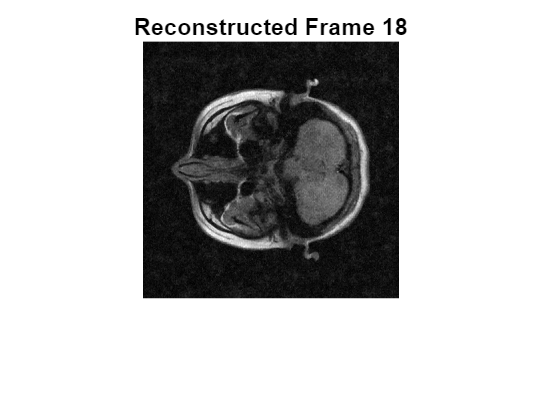

figure;
for frame = 1:num_frames
    imshow(abs(rss_CSimage(:,:,frame)), []);
    title(sprintf('Reconstructed Frame %d', frame));
    pause(0.5); % Pause for visualization
end

# Visualization of MRI Reconstruction

Visualizing MRI reconstruction results is crucial for analyzing and interpreting the data. Various visualization techniques can be employed to view and understand the reconstructed images effectively.

**Medical volume datastore **

The [`medicalVolume`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.html) function in MATLAB is used to create a medical volume object from image data. This object encapsulates the voxel data and associated metadata, such as the volume's geometry and patient coordinate system


R = medicalref3d(size(rss_CSimage));
medVolCSReconImage =medicalVolume(rss_CSimage,R);
medVolCSReconImage.VolumeGeometry.PatientCoordinateSystem ="LPS+";
voxInfo =medVolCSReconImage.Voxels;
min_val = min(voxInfo(:));
max_val = max(voxInfo(:));
normalized_data = (voxInfo(:) - min_val) / (max_val - min_val);

data =reshape(normalized_data,[256 256 18]);
newMedVol= medicalVolume(data,medVolCSReconImage.VolumeGeometry);

## Visualization Methods

#### Slice View:

Displays individual slices of the 3D reconstructed image, allowing detailed examination of each slice.

sliceViewer(newMedVol,Parent=figure)

### Volume Rendering

Provides a 3D visualization of the reconstructed image using cinematic rendering, enhancing the depth and detail of the image.

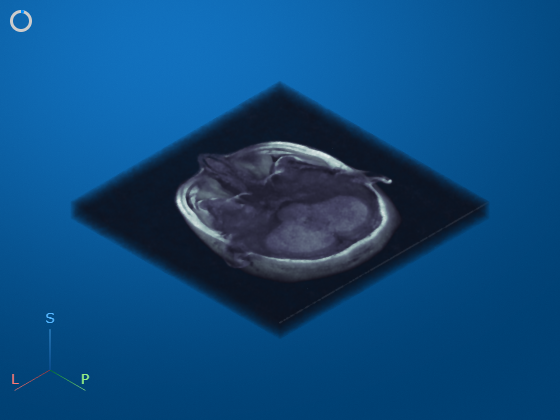

c =bone(20);
volshow(newMedVol,RenderingStyle="CinematicRendering",Colormap=c)

### Montage View

Creates a montage of slices from the 3D reconstructed image, offering a comprehensive overview of the entire volume.

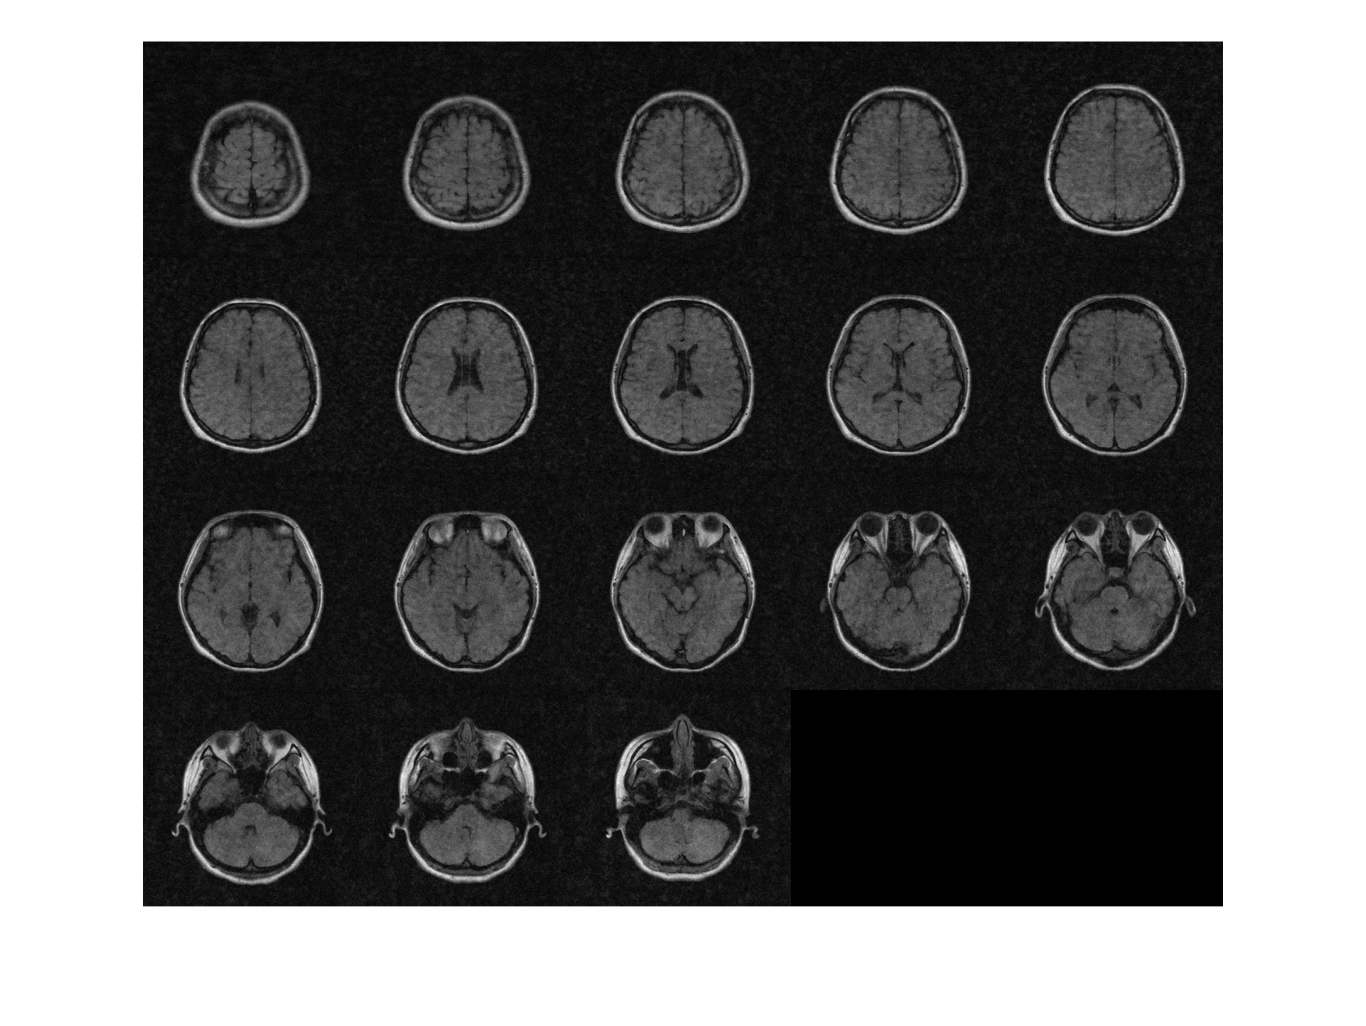

montage(newMedVol)

### Phase Encoding Direction Undersampling

In magnetic resonance imaging (MRI), k-space is a mathematical space where the raw data from the MRI scanner is stored before being transformed into an image. The k-space data is typically acquired in two dimensions: frequency encoding and phase encoding directions.

Phase encoding direction undersampling refers to selectively acquiring fewer data points in the phase encoding direction of k-space. This technique is used to reduce scan time while attempting to maintain image quality. By undersampling, we can speed up the imaging process, which is particularly useful in dynamic imaging or when patient movement is a concern.

Description ***function samplingMask = generate1DVariableDensityMask(N, density)***

This function generates a one-dimensional variable density undersampling mask for the phase encoding direction in MRI. The mask is designed to sample k-space data with varying density, focusing more on the central regions where the most significant information for image reconstruction is located.

Parameters

- N: Specifies the length of the k-space data in the phase encoding direction.

- density: Controls the shape of the density profile, influencing how densely different regions of k-space are sampled

#### Mask option 1

function samplingMask = generate1DVariableDensityMask(N, density) % Generate a 1D variable density undersampling mask
    % N: Length of the k-space data in the phase encoding direction
    % density: Parameter controlling the density profile

    % Create a polynomial density profile
    x = linspace(-1, 1, N);
    densityProfile = (1 - abs(x)).^density;

    % Generate mask based on density profile
    randomValues = rand(1, N);
    samplingMask = randomValues < densityProfile;
end

**Mask option 2**



function samplingMask = generateVariableDensityCartesianMask(m, n, density)
    % Generate a 2D variable density Cartesian undersampling mask
    % m: Number of rows in the k-space data
    % n: Number of columns in the k-space data
    % density: Parameter controlling the density profile

    % Create a polynomial density profile
    [X, Y] = meshgrid(linspace(-1, 1, n), linspace(-1, 1, m));
    densityProfile = (1 - abs(X)).^density .* (1 - abs(Y)).^density;

    % Generate mask based on density profile
    randomValues = rand(m, n);
    samplingMask = randomValues < densityProfile;
end

